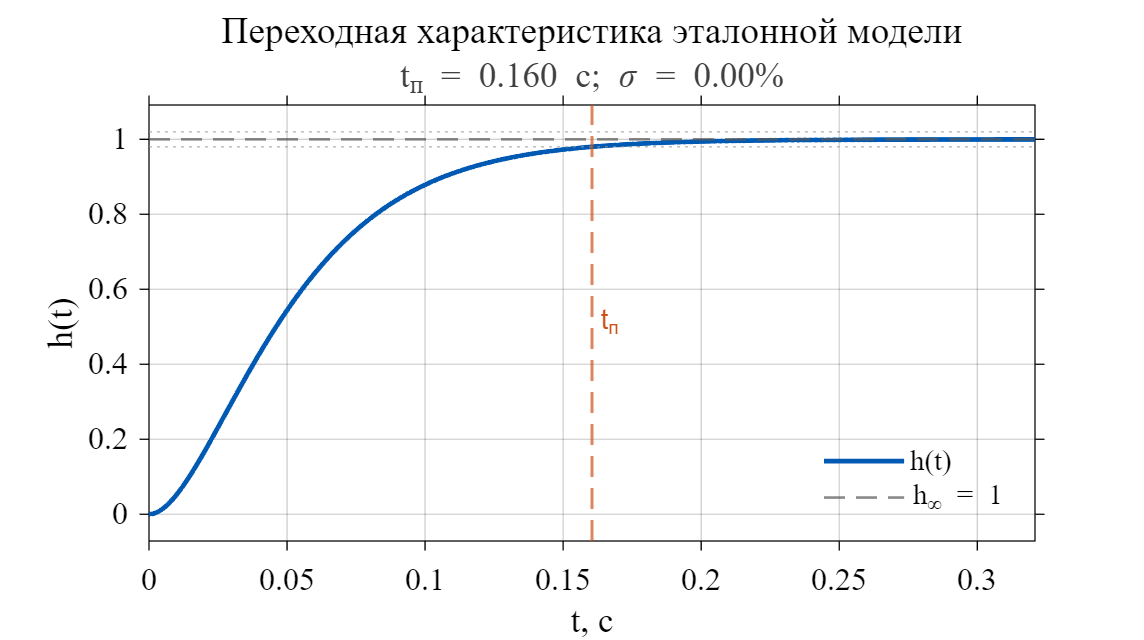

A_M = [0 1; -1329.9240 -72.9240];
B_M = [0; 1329.4782];
b_M = B_M;
out = sim('ystep');
y_st = out.y_step;
save(fullfile(fileparts(get_param('ystep', 'FileName')), 'ystep.mat'), 'y_step');

t = y_st.Time;
y = y_st.Data;
t0 = str2double(get_param('ystep/Step', 'Time'));
idx = t >= t0;
t = t(idx) - t0;
y = y(idx);

settlingBand = 0.02;
S = stepinfo(y, t, 1, 'SettlingTimeThreshold', settlingBand);

fig = figure('Color', 'white', 'Position', [100 100 1000 560]);
plot(t, y, 'LineWidth', 1.8, 'Color', [0 0.35 0.70]);
hold on;
yline(1, '--', 'Color', [0.35 0.35 0.35], 'LineWidth', 1);
yline([1-settlingBand 1+settlingBand], ':', ...
    'Color', [0.60 0.60 0.60], 'HandleVisibility', 'off');
xline(S.SettlingTime, '--', 't_{п}', 'Color', [0.80 0.32 0.10], ...
    'LineWidth', 1.1, 'LabelOrientation', 'horizontal', ...
    'LabelVerticalAlignment', 'middle', 'HandleVisibility', 'off');
set(gca, 'Color', 'white', 'FontName', 'Times New Roman', ...
    'FontSize', 12, 'XColor', 'black', 'YColor', 'black', ...
    'GridAlpha', 0.18, 'TickDir', 'out');
grid on;
box on;
xlim([0 min(t(end), 2*S.SettlingTime)]);
ylim('padded');
xlabel('t, с', 'Color', 'black');
ylabel('h(t)', 'Color', 'black');
title('Переходная характеристика эталонной модели', ...
    'FontSize', 14, 'FontWeight', 'normal', 'Color', 'black');
subtitle(sprintf('t_{п} = %.3f с; \\sigma = %.2f%%', ...
    S.SettlingTime, S.Overshoot), ...
    'Interpreter', 'tex', 'Color', [0.25 0.25 0.25]);
legend('h(t)', 'h_{\infty} = 1', 'Location', 'southeast', ...
    'Box', 'off', 'TextColor', 'black', 'Color', 'white');

imagePath = fullfile(fileparts(get_param('ystep', 'FileName')), ...
    '..', 'tex', 'images', 'reference_step.png');
exportgraphics(fig, imagePath, 'Resolution', 300, 'BackgroundColor', 'white');